Butterworth Filter:


  Filter Order: 24


  Multiplications per Sample: 60


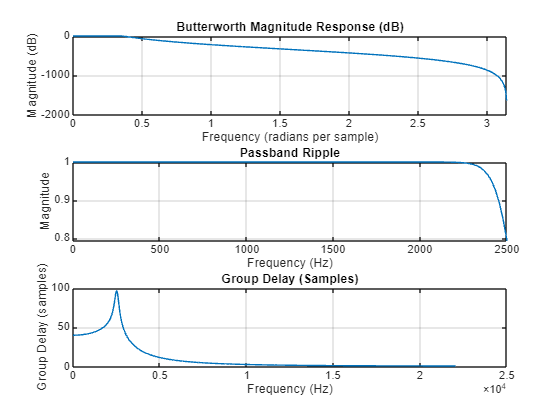

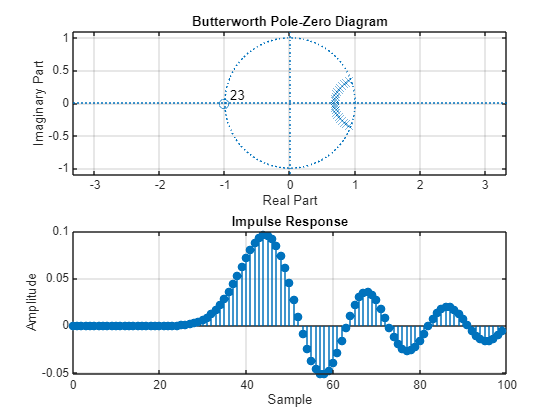

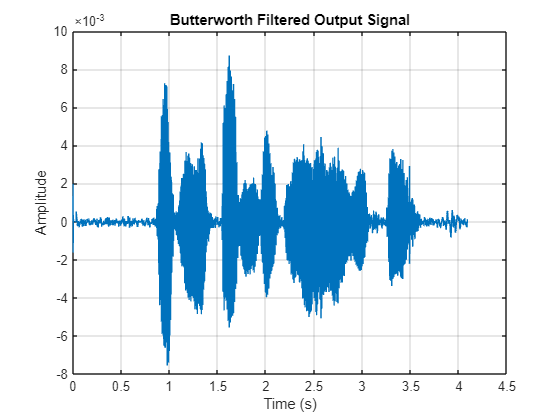

Playing Butterworth filtered output signal...


Chebyshev Type I Filter:


  Filter Order: 12


  Multiplications per Sample: 30


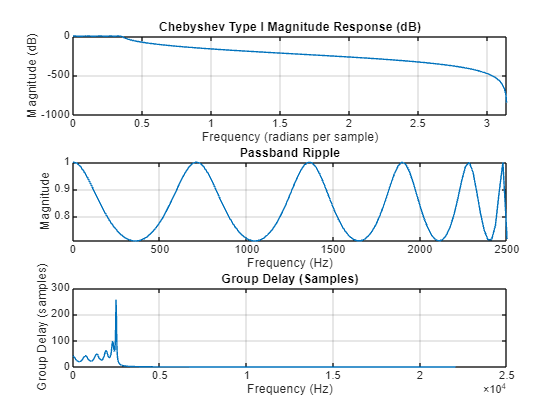

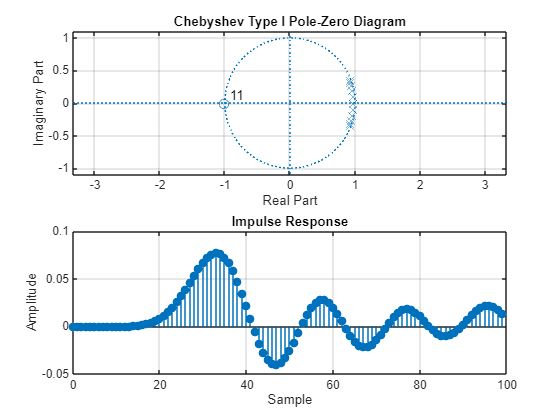

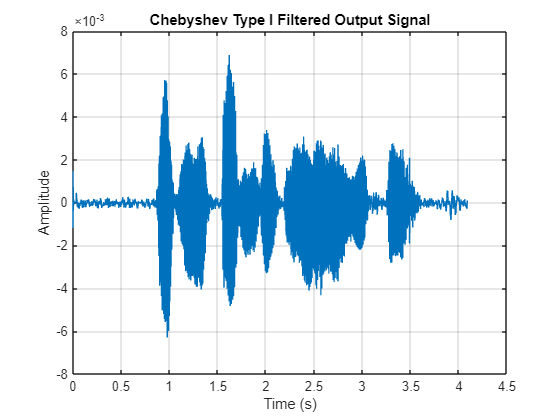

Playing Chebyshev Type I filtered output signal...


Chebyshev Type II Filter:


  Filter Order: 12


  Multiplications per Sample: 30


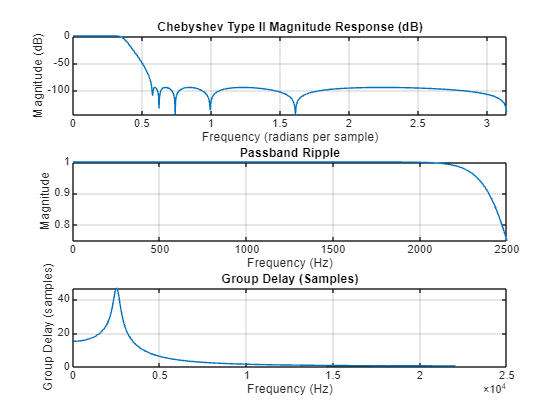

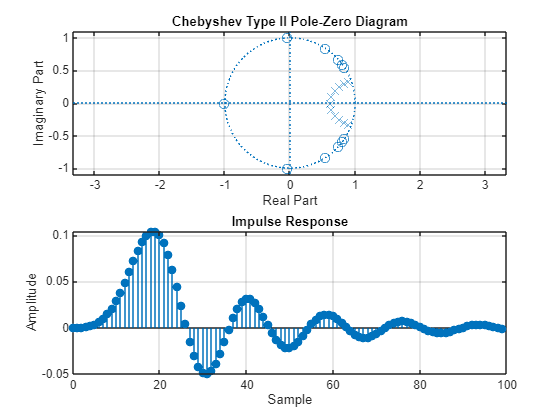

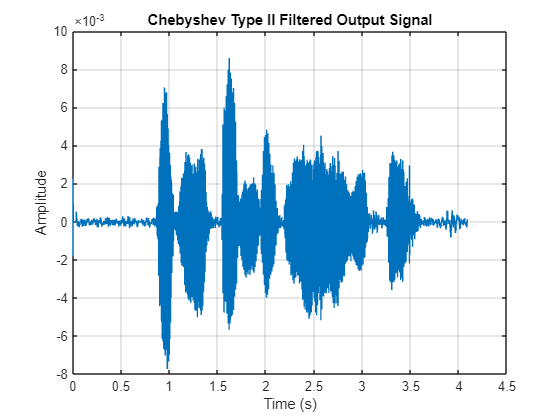

Playing Chebyshev Type II filtered output signal...


Elliptic Filter:


  Filter Order: 8


  Multiplications per Sample: 20


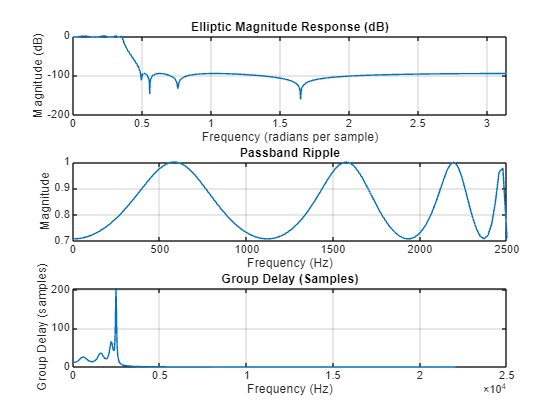

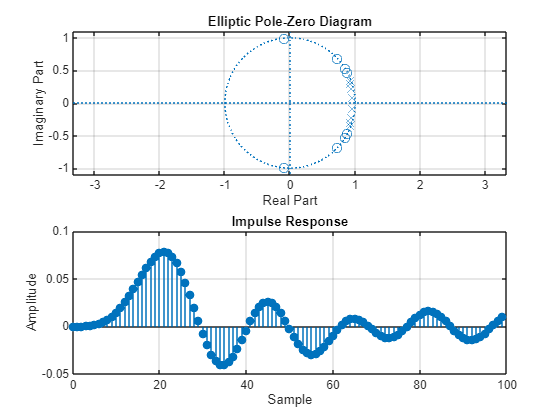

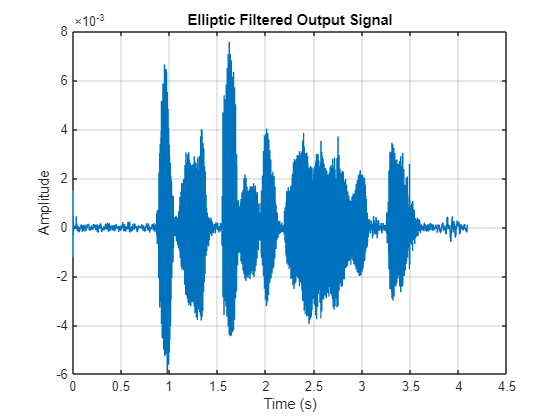

Playing Elliptic filtered output signal...


Parks-McClellan Filter:


  Filter Order: 58


  Multiplications per Sample: 59


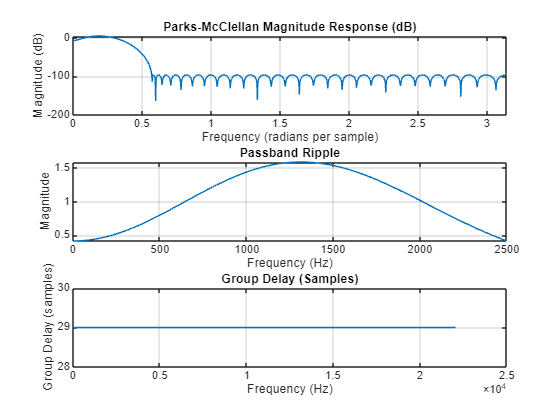

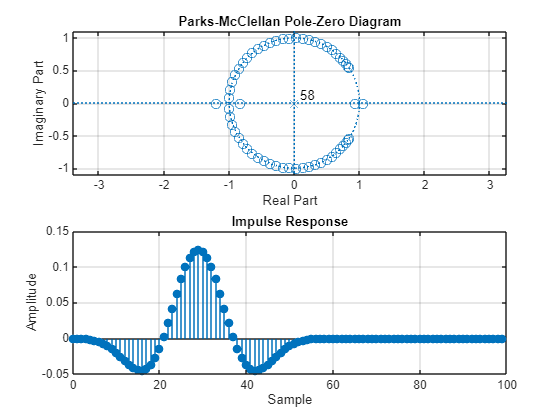

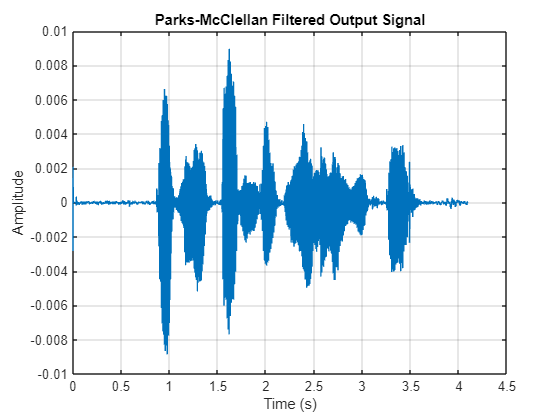

Playing Parks-McClellan filtered output signal...


Kaiser Filter:


  Filter Order: 179


  Multiplications per Sample: 180


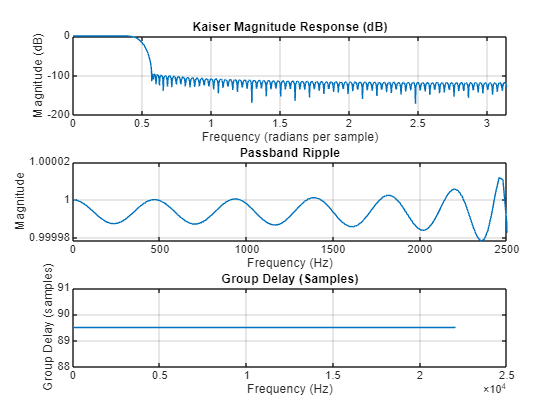

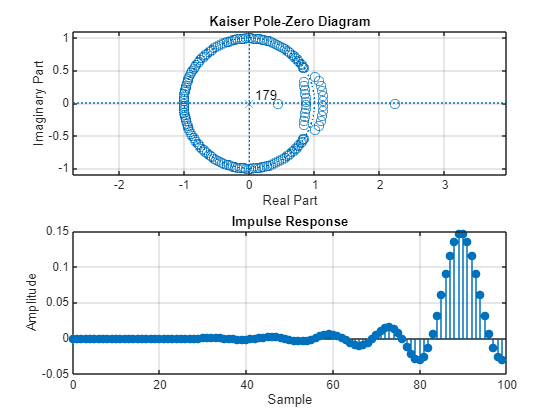

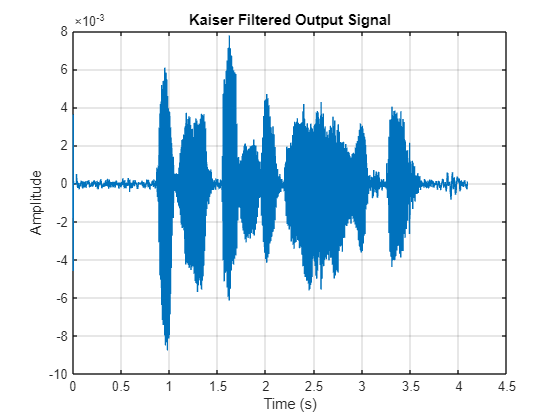

Playing Kaiser filtered output signal...


clear; clc; close all;
load projIB.mat;

Fs_in = 44100;
Fs_out = Fs_in / 4;

% Filter Specifications
max_multiplications = 17;
passband_edge = 4000;
stopband_edge = 4000;
max_gain_passband = 40;
min_gain_passband = 37;
max_gain_stopband = -55;

Ast = max_gain_passband - max_gain_stopband; % Stopband Attenuation

x = noisy;
t = (0:length(x)-1) / Fs_in;

function [sos, filter_order, num_multiplications, z, p] = butterworth_filter_(Fp, Fs_stop, Rp, Rs, Fs)
    Wp = Fp / (Fs / 2);
    Ws = Fs_stop / (Fs / 2);
    [N, Wn] = buttord(Wp, Ws, Rp, Rs);
    [z, p, k] = butter(N, Wn, 'low');
    sos = zp2sos(z, p, k);
    filter_order = 2 * size(sos, 1);
    num_multiplications = 5 * size(sos, 1);
end


filter_name = "Butterworth";
filter_func = butterworth_filter_;

if contains(filter_name, 'Parks-McClellan') || contains(filter_name, 'Kaiser')
    [b, filter_order, num_multiplications] = filter_func(Fp, Fs_stop, Rp, Rs, Fs_in);
    % FIR filter response and group delay calculations
    [H, W] = freqz(b, 1, 1024, Fs_in);
    [gd, W_gd] = grpdelay(b, 1, 1024, Fs_in);
    y = filter(b, 1, x); % FIR filter
else
    [sos, filter_order, num_multiplications, z, p] = filter_func(Fp, Fs_stop, Rp, Rs, Fs_in);
    % IIR filter response and group delay calculations
    [H, W] = freqz(sos, 1024, Fs_in);
    [gd, W_gd] = grpdelay(sos, 1024, Fs_in);
    y = sosfilt(sos, x); % IIR filter
end

% Display filter details
fprintf('%s Filter:\n', filter_name);
fprintf('  Filter Order: %d\n', filter_order);
fprintf('  Multiplications per Sample: %d\n', num_multiplications);

% Plot magnitude response, passband ripple, and group delay
figure('Name', [filter_name ' Frequency Response Analysis']);

% Magnitude Response Plot (dB vs radians)
subplot(3, 1, 1);
plot(2 * pi * W / Fs_in, 20*log10(abs(H)));
title([filter_name ' Magnitude Response (dB)']);
xlabel('Frequency (radians per sample)');
ylabel('Magnitude (dB)');
grid on;
xlim([0, pi]);

% Passband Ripple Plot
subplot(3, 1, 2);
plot(W, abs(H));
title('Passband Ripple');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xlim([0 Fp]);

% Group Delay Plot
subplot(3, 1, 3);
plot(W_gd, gd);
title('Group Delay (Samples)');
xlabel('Frequency (Hz)');
ylabel('Group Delay (samples)');
grid on;

% Plot filtered signal
figure('Name', [filter_name ' Filtered Signal']);
plot(t, y);
title([filter_name ' Filtered Output Signal']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Play filtered signal
disp(['Playing ', filter_name, ' filtered output signal...']);
soundsc(y, Fs_in);
pause(length(y) / Fs_in + 1);